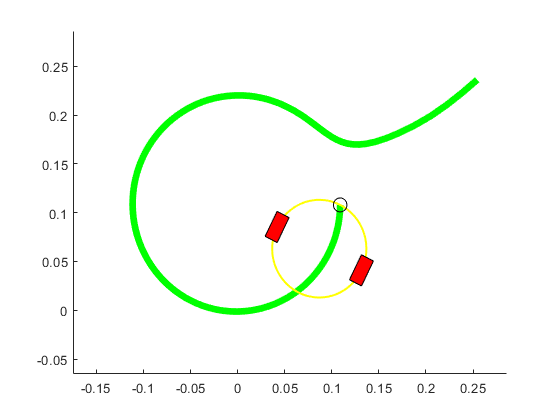

clear all
clear 
clc

map = importdata("position_Array.mat");
% map = map';% recieve path
position = importdata('circle_basepoint.mat'); % points for robot centroid path
r = .05; % base robot circle radius 
r2 = r/7; % pin radius
d = r/3.5; % size of wheels

% calculate points for wheels and pin location
xb(1,:) = position(1,:) + r*cos(position(3,:));
xb(2,:) = position(2,:) + r*sin(position(3,:));
topWheel(1,:) = position(1,:) + r*cos(pi/2+position(3,:));
topWheel(2,:) = position(2,:) + r*sin(pi/2+position(3,:));
bottomWheel(1,:) = position(1,:) - r*cos(pi/2+position(3,:));
bottomWheel(2,:) = position(2,:) - r*sin(pi/2+position(3,:));

% plot initial wheels and pin location
[xcircle,ycircle] = circle(position(:,1),r);
[x2circle,y2circle] = circle(xb(:,1),r2);
[a1,b1] = rectangle(topWheel(:,1), position(3,1),d);

% plot Map and initial position 
figure

hold on
xlim([min(position(1,:))-1.5*r max(position(1,:))+1.5*r])
ylim([min(position(2,:))-1.5*r max(position(2,:))+1.5*r])

h3 = plot(xb(1,1), xb(2,1),'Color','g','linewidth',5);
h1 = plot(xcircle, ycircle,'y','linewidth',1.5);
h2 = plot(x2circle,y2circle,'k');
Wheel1 = fill(a1, b1,'r');
Wheel2 = fill(a1, b1,'r');
% legend('Reference Trajectory', 'Robot', "location", 'best')

% plot robot location at each positon and update plot
for k = 1:length(position)
    [a,b] = circle(position(:,k), r);
    [x2circle,y2circle] = circle(xb(:,k), r2);
    [a1,b1] = rectangle(topWheel(:,k), position(3,k),d);
    set(Wheel1, 'XData', a1,'YData', b1);
    
    current_posx(k) = xb(1,k);
    current_posy(k) = xb(2,k);  

    set(h3, 'XData',  current_posx, 'YData', current_posy)

    [a1,b1] = rectangle(bottomWheel(:,k), position(3,k),d);
    set(Wheel2, 'XData', a1,'YData', b1);
    set(h1, 'XData',a,'YData', b);
    set(h2, 'XData', x2circle,'YData', y2circle);
    drawnow
  frame(k) = getframe(gcf);
end

video = VideoWriter('circle','MPEG-4');
video.FrameRate = 30;
open(video)
writeVideo(video, frame);
close(video);

function [a,b] = circle(position,r) % function to plot circle
    th = 0:pi/100:2*pi; % plot circle with step size of pi/100
    a = r*cos(th)+position(1); % x position
    b = r*sin(th)+position(2); % y location
end

function [a1,b1] = rectangle(x,theta,d) % function to plot rectangle
% initialize distances between edges of the rectangle 
sx = [-d  d  d  -d]; 
sy = [-d/2  -d/2  d/2  d/2];
% calcualte 1x4 array with final ege points
a1 = sx*cos(theta) - sy*sin(theta) + x(1);
b1 = sx*sin(theta) + sy*cos(theta) + x(2);
end